% Function to calculate the surface heat transfer coefficient, assuming
% that an empirical equation of the form {Nu=a Re^n * Pr^m * Gr^q} is available to
% approximate the local rheological and thermophysical properties of the
% fluid film in contact with the solid surface

function h=NatConvecCoeff(rho_air,mu_m,k_m,cp_m,symtype,Lc,ambtemp,Ts)


Computing the Prandtl Number (which is dependent only on the fluid and the fluid state)

where:

 of the moist air

$\alpha$            Thermal diffusivity of the moist air

k               thermal conductivity of the moist air (W/m C)

Pr=cp_m*mu_m/k_m;

Computing the Grashof Number 

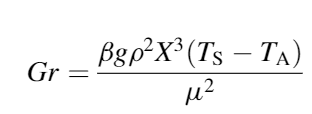

where:

 is the volumetric expansion coefficient for any gas at constant temperature, and  is the absolute air temperature in Kelvin

g is gravitational acceleration

X is a length dimension

beta=1/(ambtemp+273.15);
Gr=beta*9.81*rho_air^2*Lc^3*abs(Ts-ambtemp)/mu_m^2;

Computing the Nusselt Number

For a sphere:

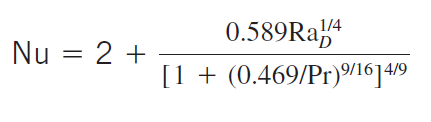

if symtype==2 % sphere
A=0.589*(Gr*Pr).^(1/4);
B=(0.469/Pr).^(9/16);
Nu=2+A/((1+B).^(4/9));

elseif symtype==1 % horizontal cylinder
    

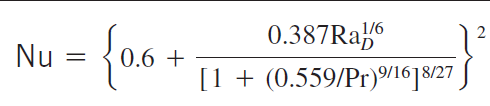

    
    A=0.387*(Pr*Gr).^(1/6);
    B=(1+(0.559/Pr).^(9/16)).^(8/27);
    Nu=(0.6+A/B).^2;
else
    error('Error. \n Use of stacked slab geometries not recommended.')
end

Solving the defining equation of the Nusselt Number to get h, the convection coefficient:

h=Nu*k_m/Lc;
end